Verifying impulse response of 1/(1+s)

- impulse response of tf=1/(1+s)

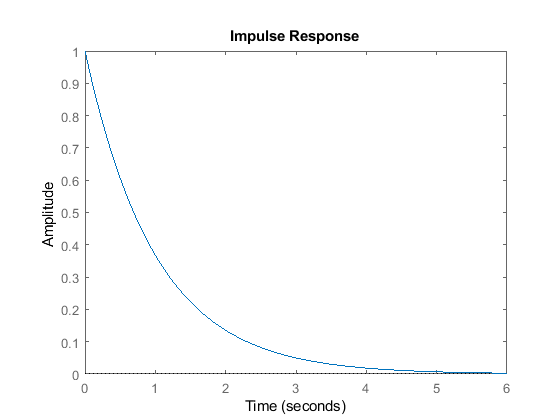

Current plot held


s=tf('s');
stf=1/(1+s);
figure(1)
impulse(stf)
hold

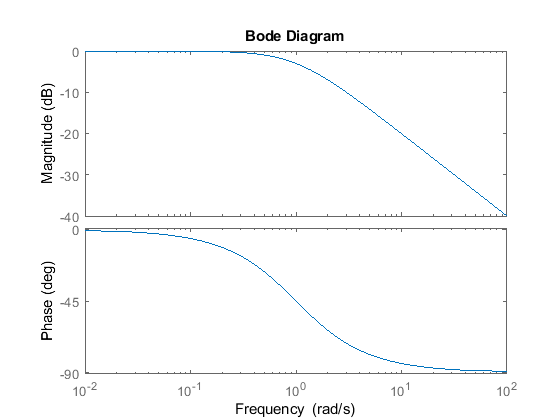

Current plot held


figure(2)
bode(stf)
hold

- ztf=c2d(1/1+s, 0.01)

Ts=.01;
ztf=c2d(1/(1+s), Ts,'tustin')


ztf =
 
  0.004975 z + 0.004975
  ---------------------
        z - 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.



- impulse response of ztf

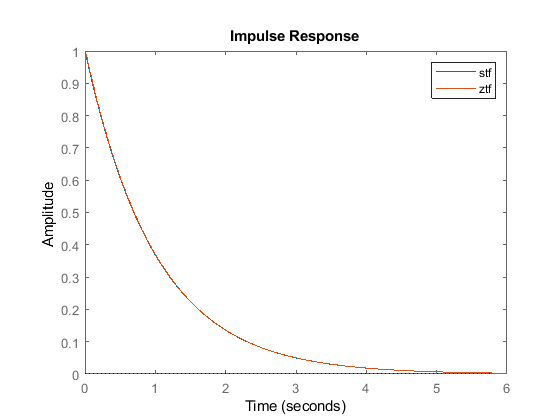

figure(1)
impulse(ztf,[0:Ts:6])
legend

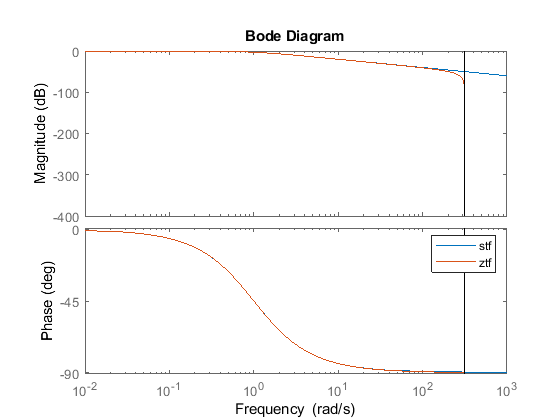

figure(2)
bode(ztf)
legend